**Problem 1)**

Our data points will be distributed in a Gaussian distribution. The precision of the thermometer will give a sigma of 0.4 and the average temperature of the device will give a mean of 12. 

**a)1. **

distr = a*randn(100k) + mean

sigma = 0.4

sigma = 0.4000

mean = 12

mean = 12

distr = sigma.*randn(100000,1) + mean

distr =    11.7026
   12.6529
   10.8688
   11.7225
   12.5000
   11.9770
   11.5430
   12.1389
   12.2509
   11.7078


distr(100001,1) = 10

distr =    11.7026
   12.6529
   10.8688
   11.7225
   12.5000
   11.9770
   11.5430
   12.1389
   12.2509
   11.7078


distr(100002,1) = 10.3

distr =    11.7026
   12.6529
   10.8688
   11.7225
   12.5000
   11.9770
   11.5430
   12.1389
   12.2509
   11.7078


distr(100003,1) = 2.1

distr =    11.7026
   12.6529
   10.8688
   11.7225
   12.5000
   11.9770
   11.5430
   12.1389
   12.2509
   11.7078


distr(100004,1) = 0

distr =    11.7026
   12.6529
   10.8688
   11.7225
   12.5000
   11.9770
   11.5430
   12.1389
   12.2509
   11.7078


distr(100005,1) = 0

distr =    11.7026
   12.6529
   10.8688
   11.7225
   12.5000
   11.9770
   11.5430
   12.1389
   12.2509
   11.7078


distr(100006,1) = 15.6

distr =    11.7026
   12.6529
   10.8688
   11.7225
   12.5000
   11.9770
   11.5430
   12.1389
   12.2509
   11.7078


distr(100007,1) = 22.3

distr =    11.7026
   12.6529
   10.8688
   11.7225
   12.5000
   11.9770
   11.5430
   12.1389
   12.2509
   11.7078


distr(100008,1) = 12.7

distr =    11.7026
   12.6529
   10.8688
   11.7225
   12.5000
   11.9770
   11.5430
   12.1389
   12.2509
   11.7078


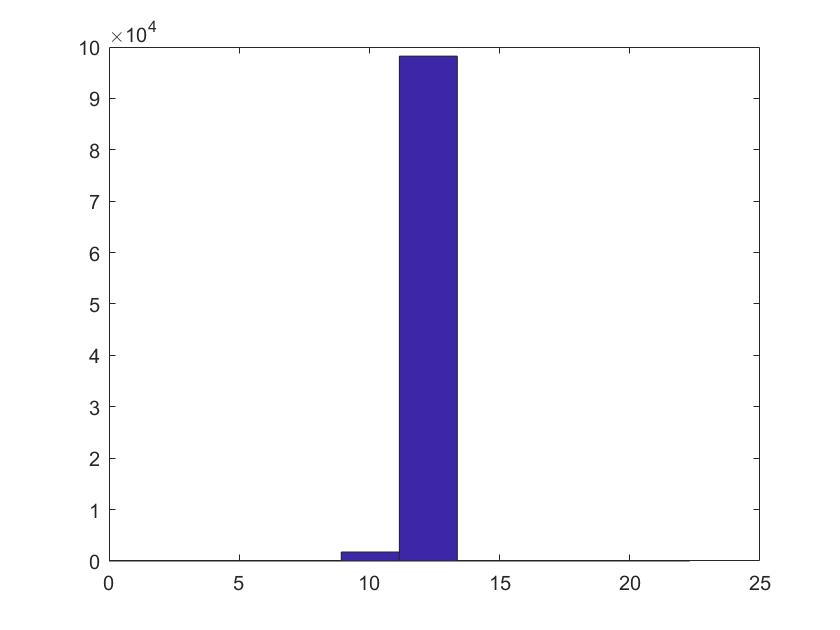


hist(distr)

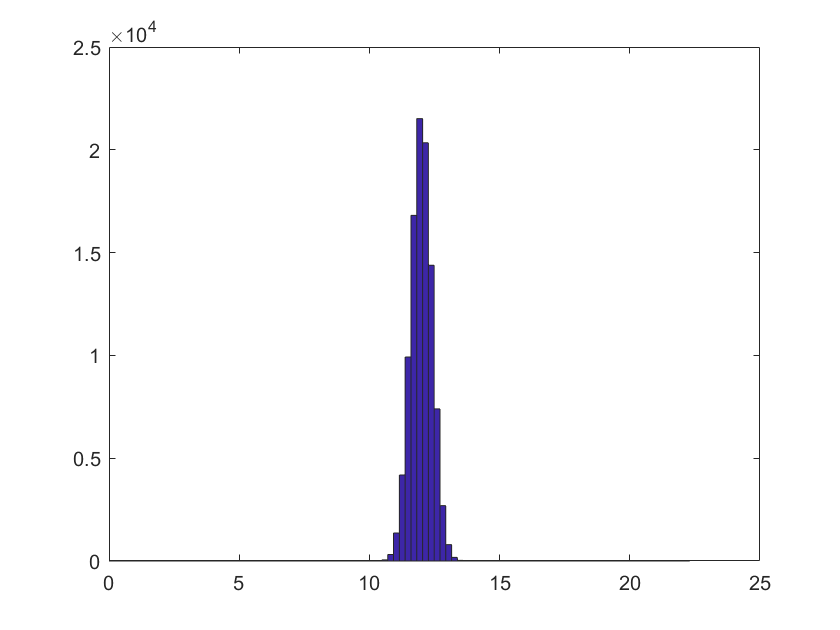


hist(distr,100)

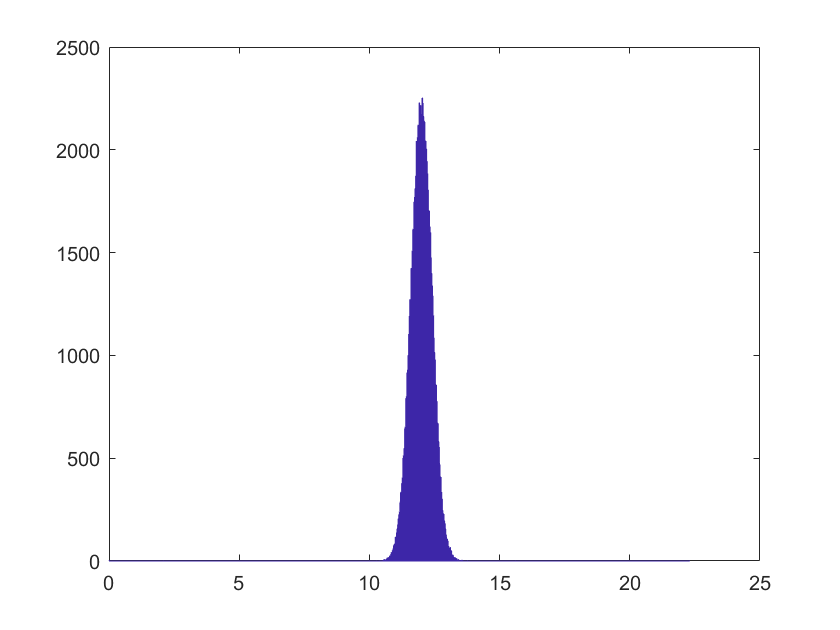


hist(distr,1000)

**2.** We assume we are given a distribution of temperature readings and we do not know which readings are good or bad data, and we do not know how much bad data that we have. A temperature reading outside of the parameters for usable data may be caused by bad temperature control(i.e. good thermometry and a true temperature of say 50 K), or bad thermometry(i.e. a temperature of twelve and a thermometry reading of 50K). Either way, we will treat measurements taken with temperature readings outside of our threshold as unusable. Which data points can we treat as being a statistical discovery of temperature different from our expected temperature of twelve? Or in other words which data points lie outside of temperature corresponding to a probability with a sigma of 5?

**3.** 

The probability corresponding to a measurement of 5 sigma will be equal to to the integral of our distribution from the value of the mean plus 5 multiplied by sigma to infinity. Any temperature measurement outside of this mean plus 5*sigma will be treated as a discovery of faulty temperature control and we will throw that data out. We can find the value corresponding to a probability corresponding to 5 sigma by taking the mean and adding 5*sigma because we are working with a normal distribution- and this is the very definition of a normal distribution. Because our mean is 12 and our sigma is 0.4, any values in our distribution lower than 10 or higher than 14 we will discard because of bad thermometry. 

%prob = normcdf(sigma)
%norminv(prob using our Gaussian parameters) = x
prob = 1-normcdf(5)

prob = 2.8665e-07

norminv(2.8665e-07,12,0.4)

ans = 10.0000

 **4**) We'll use MATLAB to take counts of all the different bins in our histogram. At the same time we'll make a vector of the center of all of the bins. Then we'll check the centers vector by hand to see which bins are over the limits of 10 and 14, and we will sum the counts vector over all of those bins to get the number of data points we are throwing out. Since we know which values of the bad data we're keeping and throwing out, we'll put those values in the False column of our Truth table and then subtract them from the corresponding sums of the different bins in the counts vector we will but in the True column of our Truth table. 

[counts,centers] = hist(distr,1000)

counts =      2     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


centers =     0.0112    0.0335    0.0558    0.0781    0.1003    0.1227    0.1449    0.1672    0.1895    0.2119    0.2341    0.2565    0.2787    0.3011    0.3233    0.3457    0.3679    0.3903    0.4126    0.4348    0.4572    0.4794    0.5018    0.5241    0.5464    0.5686    0.5910    0.6132    0.6355    0.6579    0.6802    0.7025    0.7248    0.7470    0.7694    0.7916    0.8140    0.8363    0.8585    0.8809    0.9032    0.9255    0.9477    0.9700    0.9924    1.0147    1.0370    1.0593    1.0816    1.1038


test = sum(centers(1,1:2))

test = 0.0446

Our centers column 448 has the value 9.9793, and column 449 has the value 10.0016, so we will sum the first 448 columns of our counts vector(Our bad data point of 10 will also be included in the positive row, since it is closer to the center value of 10.0016 than 9.9793). Meanwhile center column 628 has the value 13.9933, while center column 629 has the value 14.0156, so we will sum the last 372 columns of our counts vector and add it to our other sum for our total sum of data points outside of our values corresponding to 5 sigma. 

sum1 = sum(counts(1,1:448))

sum1 = 3

sum2 = sum(counts(1, 629:1000))

sum2 = 2

Table = {'positive'; 'negative'}

Table = 2×1 cell array
    {'positive'}
    {'negative'}


True = zeros(2,1)

True =      0
     0


True(1,1) = 100000

True =       100000
           0


True(2,1) = 0

True =       100000
           0


False = zeros(2,1)

False =      0
     0


False(1,1) = 3

False =      3
     0


False(2,1) = 5

False =      3
     5


Tab = table(Table,True,False)

Tab = 2×3 table
       Table        True     False
    ____________    _____    _____

    {'positive'}    1e+05      3  
    {'negative'}        0      5  


**B)** Our distribution of good data is a purely Gaussian distribution. Because we know the distribution, the amount of omissions can be directly tied to the sigma threshold we pick. For example, because 5 sigma corresponds to a roughly 1/3.5e-6 probability, and we have a sample of 100000 good data poins in our Gaussian distribution, we could easily have predicted our result of 0 omissions. 

More broadly, we know that a statistical sigma threshold is directly correlated to a probability, and if we know the probability a data point will be over our statistical threshold and our number of data points we can predict how likely it is we will have an omission. Since we have 10e4 random data points, and there is a 1/3.5e-6 chance of a data point in that distribution being over our threshold, there is approximately a 3% chance of us omitting a data point in our distribution. 

**C)**